% read an input 

train1_1 = imread('train_images/Set1/1.jpg');
train1_2 = imread('train_images/Set1/2.jpg');
train1_3 = imread('train_images/Set1/3.jpg');


## To Grayscale

train1_1 = rgb2gray(train1_1);
train1_2 = rgb2gray(train1_2);
train1_3 = rgb2gray(train1_3);

## Corner Detection

cm1_1 = cornermetric(train1_1);
cm1_2 = cornermetric(train1_2);
cm1_3 = cornermetric(train1_3);


## ANMS Test

Nbest = 200;

lm1_1 = imregionalmax(cm1_1);


[x,y] = find(lm1_1);

N_Strong = size(x,1);

r = inf(1,N_Strong);
ED = 0;

for i = 1:N_Strong
    for j = 1:N_Strong
        if cm1_1(x(j),y(j)) > cm1_1(x(i),y(i))
           ED =  (x(j)-x(i))^2 + (y(j)-y(i))^2;
           if ED < r(i)
              r(i) = ED;
           end 
        end
    end
end    

[sort_r,index] = sort(r,'descend');


## Test function


a = [2 4 6 8 10]
b = find(a > 3)

## ANMS Step

Nbest = 200;
c_best_1_1 = ANMS(cm1_1,Nbest);
c_best_1_2 = ANMS(cm1_2,Nbest);
c_best_1_3 = ANMS(cm1_3,Nbest);


## display


imshow(train1_1);
hold on;
scatter(c_best_1_1(2,:),c_best_1_1(1,:),'r.')
hold off;

imshow(train1_2);
hold on;
scatter(c_best_1_2(2,:),c_best_1_2(1,:),'r.')
hold off;

imshow(train1_3);
hold on;
scatter(c_best_1_3(2,:),c_best_1_3(1,:),'r.')
hold off;



## Feature Descriptor

H = fspecial('gaussian',40,0.5);

f_vector_1_1 = f_descriptor(c_best_1_1,train1_1,H);
%f_vector_1_2 = f_descriptor(c_best_1_2,train1_2,H);
%f_vector_1_3 = f_descriptor(c_best_1_3,train1_3,H);


## test


test1 = f_vector_1_1(:,7)

test1 =     1.0538
    1.0425
    1.0425
    1.0425
    1.0538
    0.0186
   -1.0390
   -1.1628
    1.0538
    1.0538


mean_1 = mean(test1)

mean_1 = -9.7145e-17

var_1 = var(test1)

var_1 = 1.0000

## Feature Matching

clear matchedpts1
clear matchedpts2
% ssd
index = 1;
mp_1_1_2 = zeros(2,size(c_best_1_2,2));
for i = 1:size(f_vector_1_1,2)
b_ssd = 1000000;
sb_ssd = 1000000;
    for j = 1:size(f_vector_1_2,2)
        ssd = 0;
        for k = 1:64 
            ssd = ssd + ((f_vector_1_1(k,i) - f_vector_1_2(k,j))^2); 
        end
        if ssd < b_ssd 
            sb_ssd = b_ssd;
            b_ssd = ssd;
            temp_1 = c_best_1_1(:,i);
            temp_2 = c_best_1_2(:,j);
                
        elseif ssd < sb_ssd 
            sb_ssd = ssd;
        end  
      
    end
    b_ssd/sb_ssd;
    if b_ssd/sb_ssd>0.95
    matchedpts1(:,index) =  temp_1;
    matchedpts2(:,index) =  temp_2;
    index = index+1;
    end
end
matchedpts1 = matchedpts1'
matchedpts2 = matchedpts2'



## Feature Matching from Deepti

clear matchedpts1
clear matchedpts2
k =1;
for i = 1:size(f_vector_1_1,2)
      first_pt = zeros(64,1);
      first = 1000000000000;
      second = 1000000000000;
    for j = 1:size(f_vector_1_2,2)
      dist = sum((f_vector_1_1(:,i) - f_vector_1_2(:,j)).^2);
        if dist <first
            second = first;
            first = dist;
            second_pt_index = j;
        elseif dist<second 
            second = dist;
        end
    end
    first/second;
    if first/second <0.5        
        matchedpts1(k,:) = [c_best_1_1(1,i),c_best_1_1(2,i)];
        matchedpts2(k,:) = [c_best_1_2(1,second_pt_index),c_best_1_2(2,second_pt_index)];
        k = k+1;
    end
    
end
matchedpts1

matchedpts1 =    282   419
   427   417
   395   297
   232   299
   586   347
   286   300
   449   297
   541   350
   107   366
   343   439


matchedpts2

matchedpts2 =    275   190
   414   191
   388    72
   223    71
   577   123
   277    73
   442    73
   530   129
    99   137
   332   209


## RANSAC

threshold = 10^2;
maxi = 30;
matchedpts1;
matchedpts2;
X = zeros(4,1);
Y = zeros(4,1);
x = zeros(4,1);
y = zeros(4,1);
percentage = 0;
% random no.
j=0;
while j <= 100 && percentage < 90
    for i = 1:4
        r = randi(size(matchedpts1,1));
        X(i,1) = matchedpts1(r,2);
        Y(i,1) = matchedpts1(r,1);
        x(i,1) = matchedpts2(r,2);
        y(i,1) = matchedpts2(r,1);
    end
    
    H = est_homography(x,y,X,Y);
    [X1, Y1] = apply_homography(H,matchedpts1(:,1), matchedpts1(:,2)) ;
    SSD(:,1) = matchedpts2(:,2) - X1 ;
    SSD(:,2) = matchedpts2(:,1) - Y1;
    SSD_n = SSD(:,1) + SSD(:,2);
    SSD_n = SSD_n.^2
    if size(SSD_n(SSD_n < threshold),1)/size(SSD_n,1)*100 > percentage 
        percentage = size(SSD_n(SSD_n < threshold),1)/size(SSD_n,1)*100
        inliers = find(SSD_n < threshold);
    end
    j = j + 1;
end

SSD_n = 	1.0e+04 *

    0.0044
    0.0055
    0.0005
    0.0000
    0.0107
    0.0001
    0.0021
    0.0060
    0.0023
    0.0160


percentage = 84.6154

SSD_n = 	1.0e+04 *

    0.0077
    0.0011
    0.0012
    0.0036
    0.1040
    0.0030
    0.0093
    0.0620
    0.0023
    0.0074


SSD_n = 	1.0e+04 *

    0.0019
    0.0001
    0.0020
    0.0003
    0.0506
    0.0000
    0.0067
    0.0300
    0.0097
    0.0078


SSD_n = 	1.0e+04 *

    0.0017
    0.0005
    0.0028
    0.0001
    0.0774
    0.0000
    0.0097
    0.0470
    0.0066
    0.0047


SSD_n = 	1.0e+04 *

    0.0238
    0.0007
    0.0001
    0.0154
    0.3081
    0.0000
    0.0090
    0.1567
    0.3074
    0.0301


SSD_n = 	1.0e+04 *

    0.0061
    0.0000
    0.0043
    0.0051
    0.0468
    0.0015
    0.0130
    0.0327
    0.0217
    0.0078


SSD_n = 	1.0e+04 *

    0.0114
    0.0009
    0.0000
    0.0003
    0.1234
    0.0013
    0.0025
    0.0644
    0.0174
    0.0105


SSD_n = 	1.0e+05 *

    0.1981
    0.7739
    0.1803
    0.0078
    1.3537
    0.0073
    0.3515
    1.0807
    0.0726
    0.4651


SSD_n = 	1.0e+05 *

    0.0007
    0.6415
    0.0018
    0.6855
    0.3849
    0.9966
    0.0232
    0.2302
    0.6441
    0.1090


SSD_n = 	1.0e+04 *

    0.0020
    0.0025
    0.0016
    0.0020
    0.1337
    0.0000
    0.0090
    0.0760
    0.0398
    0.0044


SSD_n = 	1.0e+04 *

    0.0022
    0.0023
    0.0009
    0.0000
    0.0869
    0.0003
    0.0058
    0.0512
    0.0049
    0.0028


SSD_n = 	1.0e+04 *

    0.0020
    0.0000
    0.0023
    0.0000
    0.0492
    0.0001
    0.0075
    0.0305
    0.0018
    0.0062


SSD_n = 	1.0e+05 *

    1.4510
    0.6829
    0.1543
    0.0142
    1.4519
    1.2038
    0.3623
    1.1372
    0.0168
    0.2238


SSD_n = 	1.0e+04 *

    0.0428
    0.0018
    0.0053
    0.0000
    0.5893
    0.0045
    0.0006
    0.2078
    0.0203
    0.0185


SSD_n = 	1.0e+04 *

    0.0004
    0.6813
    0.0858
    0.0061
    5.2274
    0.0005
    0.3577
    2.7809
    0.0115
    0.1163


SSD_n = 	1.0e+05 *

    0.2856
    0.0084
    0.3028
    1.1560
    0.0436
    0.8066
    0.1416
    0.0063
    1.5840
    0.0865


SSD_n = 	1.0e+04 *

    0.0006
    0.0026
    0.0010
    0.0060
    0.1581
    0.0001
    0.0079
    0.0871
    0.1246
    0.0040


SSD_n = 	1.0e+04 *

    0.0194
    0.0006
    0.0029
    0.0094
    0.1675
    0.0010
    0.0001
    0.0748
    0.2831
    0.0312


SSD_n = 	1.0e+04 *

    0.1273
    0.0130
    0.0097
    0.0889
    0.7636
    0.0716
    0.0042
    0.3251
    0.1463
    0.0277


SSD_n = 	1.0e+05 *

    0.0314
    0.0865
    0.1287
    0.0397
    1.3193
    0.0003
    0.3198
    1.5975
    0.1926
    0.0878


SSD_n = 	1.0e+04 *

    0.0000
    0.0571
    0.0003
    0.0009
    0.3928
    0.0000
    0.0086
    0.1886
    0.0137
    0.0123


SSD_n = 	1.0e+04 *

    0.0053
    0.0027
    0.0012
    0.0133
    0.2394
    0.0005
    0.0111
    0.1282
    0.2122
    0.0107


SSD_n = 	1.0e+04 *

    0.0018
    0.0008
    0.0008
    0.0200
    0.0536
    0.0092
    0.0077
    0.0372
    0.0232
    0.0027


SSD_n = 	1.0e+04 *

    0.0197
    0.0000
    0.0100
    0.0381
    0.0097
    0.0199
    0.0089
    0.0083
    0.1908
    0.0003


SSD_n = 	1.0e+05 *

    0.0167
    0.1091
    0.0612
    0.6751
    0.3675
    0.3890
    0.0034
    0.2228
    0.8684
    0.0170


SSD_n = 	1.0e+04 *

    0.0512
    0.0085
    0.0011
    0.2940
    0.2025
    0.0605
    0.0028
    0.1014
    3.4914
    0.0022


SSD_n = 	1.0e+04 *

    0.0139
    0.0127
    0.0090
    0.4947
    0.1558
    0.2070
    0.0000
    0.0173
    0.7893
    0.0413


SSD_n = 	1.0e+04 *

    0.0011
    0.3054
    0.0471
    0.0045
    2.5198
    0.0004
    0.1966
    1.3598
    0.0109
    0.0403


SSD_n = 	1.0e+04 *

    0.0025
    0.0010
    0.0021
    0.0000
    0.0898
    0.0001
    0.0091
    0.0536
    0.0055
    0.0049


SSD_n = 	1.0e+04 *

    0.0018
    0.0001
    0.0011
    0.0028
    0.0698
    0.0001
    0.0049
    0.0389
    0.0344
    0.0064


SSD_n = 	1.0e+09 *

    0.0000
    0.0003
    0.0000
    0.0000
    0.0002
    0.0000
    0.0001
    0.0002
    0.0000
    0.0000


SSD_n = 	1.0e+05 *

    0.0103
    0.0050
    0.0000
    0.0145
    0.1192
    0.0000
    0.0041
    0.0660
    0.5025
    0.0042


SSD_n = 	1.0e+05 *

    0.0110
    0.0371
    0.0009
    0.6613
    0.3084
    0.4731
    0.0032
    0.1825
    0.8675
    0.1636


SSD_n = 	1.0e+07 *

    0.0037
    0.0012
    0.0446
    0.0007
    0.0922
    0.0007
    0.1663
    0.1424
    0.0003
    0.0047


SSD_n = 	1.0e+04 *

    0.0009
    0.0000
    0.0012
    0.0175
    0.0761
    0.0029
    0.0041
    0.0397
    0.1271
    0.0075


SSD_n = 	1.0e+07 *

    0.0010
    0.0036
    0.0000
    0.0008
    0.1849
    0.0010
    0.0288
    0.5464
    0.0001
    0.0003


SSD_n = 	1.0e+04 *

    0.0061
    0.0059
    0.0024
    0.0114
    0.3520
    0.0001
    0.0197
    0.1933
    0.2990
    0.0119


SSD_n = 	1.0e+04 *

    0.0026
    0.0019
    0.0024
    0.0004
    0.1232
    0.0000
    0.0109
    0.0720
    0.0166
    0.0049


SSD_n = 	1.0e+04 *

    0.0012
    0.0000
    0.0016
    0.0000
    0.0387
    0.0001
    0.0055
    0.0242
    0.0025
    0.0048


SSD_n = 	1.0e+04 *

    0.0467
    0.0005
    0.0321
    0.4782
    0.4317
    0.1266
    0.0989
    0.0286
    1.7653
    0.0068


SSD_n = 	1.0e+06 *

    0.0068
    0.0975
    0.0440
    0.1863
    0.0409
    0.1356
    0.0652
    0.1334
    0.1822
    0.0044


SSD_n = 	1.0e+04 *

    0.0262
    0.0041
    0.0008
    0.0132
    0.2571
    0.0114
    0.0164
    0.1465
    0.0084
    0.0158


SSD_n = 	1.0e+04 *

    0.0046
    0.0002
    0.0103
    0.0110
    0.0301
    0.0014
    0.0226
    0.0277
    0.0735
    0.0047


SSD_n = 	1.0e+08 *

    0.0000
    0.0002
    0.0004
    0.0001
    0.0290
    0.0001
    0.0029
    6.4948
    0.0002
    0.0000


SSD_n = 	1.0e+07 *

    1.2537
    0.0020
    0.0000
    0.0015
    0.0106
    0.0352
    0.0013
    0.0076
    0.0000
    0.0021


SSD_n = 	1.0e+04 *

    0.0065
    0.0172
    0.0013
    0.0102
    0.1022
    0.0074
    0.0004
    0.0474
    0.0202
    0.0017


SSD_n = 	1.0e+04 *

    0.0096
    0.0002
    0.0015
    0.0000
    0.1331
    0.0006
    0.0104
    0.0743
    0.0102
    0.0136


SSD_n = 	1.0e+04 *

    0.0026
    0.0003
    0.0021
    0.0000
    0.0388
    0.0001
    0.0067
    0.0240
    0.0013
    0.0085


percentage = 87.1795

SSD_n = 	1.0e+04 *

    0.0421
    0.0002
    0.0001
    0.0168
    0.2185
    0.0151
    0.0115
    0.1187
    0.0134
    0.0316


SSD_n = 	1.0e+04 *

    0.0005
    0.0012
    0.0000
    0.0048
    0.2169
    0.0005
    0.0049
    0.1124
    0.3532
    0.0084


SSD_n = 	1.0e+05 *

    0.0095
    0.0008
    0.0004
    0.0095
    0.0875
    0.0003
    0.0046
    0.0473
    0.2259
    0.0082


SSD_n =     0.0805
    0.5900
   18.7105
   85.8059
  639.8135
   16.0610
   55.7895
  361.1390
  885.8031
   36.4420


SSD_n =     0.3223
    0.0366
    0.0450
    0.0001
    3.9309
    0.0177
    0.3137
    2.2011
    0.3173
    0.2844


SSD_n =     0.0567
    0.4621
    0.2271
    0.0000
    6.2858
    0.0007
    0.7916
    3.9092
    0.1939
    0.0089


SSD_n =     0.3071
    0.0251
    0.0485
    0.1370
    2.6401
    0.0789
    0.2986
    1.5590
    0.2461
    0.2148


SSD_n =     0.0242
    0.1319
    0.0123
    0.2120
    0.9518
    0.0396
    0.0057
    0.3274
    1.2239
    0.0746


SSD_n =     0.0194
    0.0022
    0.0231
    0.3952
    1.5772
    0.0678
    0.0862
    0.8174
    3.1641
    0.1149


SSD_n =     0.0004
    0.1112
    2.1037
    1.8123
    5.6494
    1.5137
    3.6296
    2.1352
    1.9110
    0.1468


SSD_n =     4.8610
    2.6375
   30.8114
    1.4421
  646.5526
    0.0259
   95.7372
  402.2547
   96.2962
   38.8886


SSD_n =     0.0080
    0.0009
    0.0145
    0.2288
    0.9640
    0.0392
    0.0513
    0.5045
    1.6776
    0.0723


SSD_n =    19.2598
    2.3559
   13.2713
   20.0368
  152.7897
    8.4609
   42.7170
  113.2707
   44.1569
   52.2293


percentage = 89.7436

SSD_n =     0.0000
    0.0002
    0.0000
    0.0105
    0.4338
    0.0033
    0.0003
    2.2989
    0.0279
    0.0008


SSD_n =     0.0862
    0.7209
    0.4550
    0.1820
    4.4253
    0.0048
    1.0968
    3.1210
    1.9044
    0.0108


SSD_n =     0.0054
    0.1409
    0.0299
    0.0008
    0.5822
    0.0001
    0.0924
    0.4081
    5.5682
    0.0132


SSD_n =     0.0000
    0.0000
    0.0000
    0.0003
    0.0000
    0.0000
    0.0000
    0.0000
    1.7326
    0.0000


SSD_n =    10.3521
  202.0789
    1.0237
    0.7547
  321.7602
    0.0139
    0.5222
  155.0594
    7.1688
  139.5617


SSD_n =     0.0584
    0.0194
    0.0308
    0.8720
    1.2422
    0.5414
    0.0194
    0.7282
    0.4426
    0.0440


SSD_n =    23.8211
    0.0033
   11.2997
   11.3096
  605.8658
    0.0770
   50.4994
  342.5822
  185.3897
   73.9921


SSD_n =     0.3641
    0.1197
    0.0101
    0.0196
    4.6245
    0.0768
    0.2346
    2.5767
    0.1831
    0.1911


SSD_n =    26.2908
   21.8712
   10.8021
   23.1909
   19.9510
    7.5511
   26.3272
   23.0612
   95.9437
   76.4917


SSD_n =     0.0032
    0.0057
    0.0000
    0.0536
    0.1164
    0.0020
    0.0027
    0.0637
    3.2017
    0.0023


SSD_n =     0.0000
    0.0028
    0.0000
    0.0000
    0.0006
    0.0000
    3.1261
    0.0007
    0.0000
    0.0000


SSD_n =     0.1139
    0.5745
    0.0999
    0.0404
    1.1850
    0.0006
    0.2778
    0.9230
    0.1476
    0.3309


SSD_n =    41.1413
    3.3740
    9.9386
    1.8514
  444.3574
    4.8399
   50.1883
  260.2321
   13.3977
   98.7810


SSD_n =     0.3393
    0.9654
    0.2830
    0.0054
    1.3106
    0.0546
    0.4449
    1.1419
    0.0098
    0.6503


SSD_n =     0.0000
    0.1248
    0.0120
    0.0005
    0.1387
    0.0162
    0.0288
    0.1116
    0.0136
    3.2080


SSD_n =     0.0007
    0.0004
    0.0001
    0.0066
    0.5135
    0.0016
    0.0022
    1.9200
    0.0190
    0.0024


SSD_n =    16.2588
    2.6375
   50.8321
   69.1786
  425.3722
   16.5460
  145.5699
  322.5271
  182.4925
   35.7523


SSD_n =     0.0303
    0.0530
    0.0338
    0.0009
    1.6044
    0.0046
    0.1551
    0.9649
    0.0455
    0.0321


SSD_n =     0.2221
    1.9167
    0.1974
    2.7937
    6.3799
    1.4873
    0.6712
    4.4684
    4.4564
    4.2718


SSD_n =     0.0009
    0.0093
    0.0201
    0.0001
    0.1147
    0.0001
    4.0530
    0.1777
    0.0000
    0.0004


SSD_n =     0.1861
    0.0744
    0.0010
    0.1640
    1.9294
    0.1551
    0.0565
    1.0913
    0.1663
    0.0651


SSD_n =    38.5845
    0.8455
    5.9949
    0.0324
  440.5820
    3.3225
   36.4917
  253.2352
   25.6649
   82.5062


SSD_n =    10.3194
    5.0919
   17.3265
    1.8517
  136.1099
    0.7293
   43.1432
   99.1083
    0.5294
   52.9111


percentage = 92.3077

percentage

percentage = 92.3077

inliers;

inliers_1 = matchedpts1(inliers,:)

inliers_1 =    282   419
   427   417
   395   297
   232   299
   286   300
   449   297
   541   350
   107   366
   343   439
   114   404


inliers_2 = matchedpts2(inliers,:)

inliers_2 =    275   190
   414   191
   388    72
   223    71
   277    73
   442    73
   530   129
    99   137
   332   209
   109   172





H = est_homography(inliers_1(:,1),inliers_1(:,2),inliers_2(:,1),inliers_2(:,2))

H =     0.0041   -0.0003    0.0733
   -0.0001    0.0037    0.9973
   -0.0000   -0.0000    0.0043


[X1, Y1] = apply_homography(H,inliers_1(:,1), inliers_1(:,2));  
match_1 = [X1 Y1]

match_1 =   292.6686  678.0607
  452.4020  673.5669
  411.5546  533.5349
  238.8184  538.2666
  296.0140  538.5752
  468.9094  532.7118
  571.7892  592.1020
  103.2631  617.2207
  360.4471  701.6980
  108.8867  662.2991


[X2, Y2] = apply_homography(H,inliers_2(:,1), inliers_2(:,2));  
match_2 = [X2 Y2] 

match_2 =   283.8315  418.7425
  426.5157  417.5805
  395.2535  296.6593
  231.8878  298.4185
  285.2903  299.4893
  448.8939  296.7447
  540.8154  351.3897
  106.4035  366.5694
  342.6963  437.9975
  114.8648  402.5168


## Show

figure; ax = axes;
showMatchedFeatures(train1_1,train1_2,matchedpts1,matchedpts2,'montage','Parent',ax);

newm1 =    419
   417
   297
   299
   347
   300
   297
   350
   366
   439


newm1 =    419   282
   417   427
   297   395
   299   232
   347   586
   300   286
   297   449
   350   541
   366   107
   439   343


newm2 =    190
   191
    72
    71
   123
    73
    73
   129
   137
   209


newm2 =    190   275
   191   414
    72   388
    71   223
   123   577
    73   277
    73   442
   129   530
   137    99
   209   332


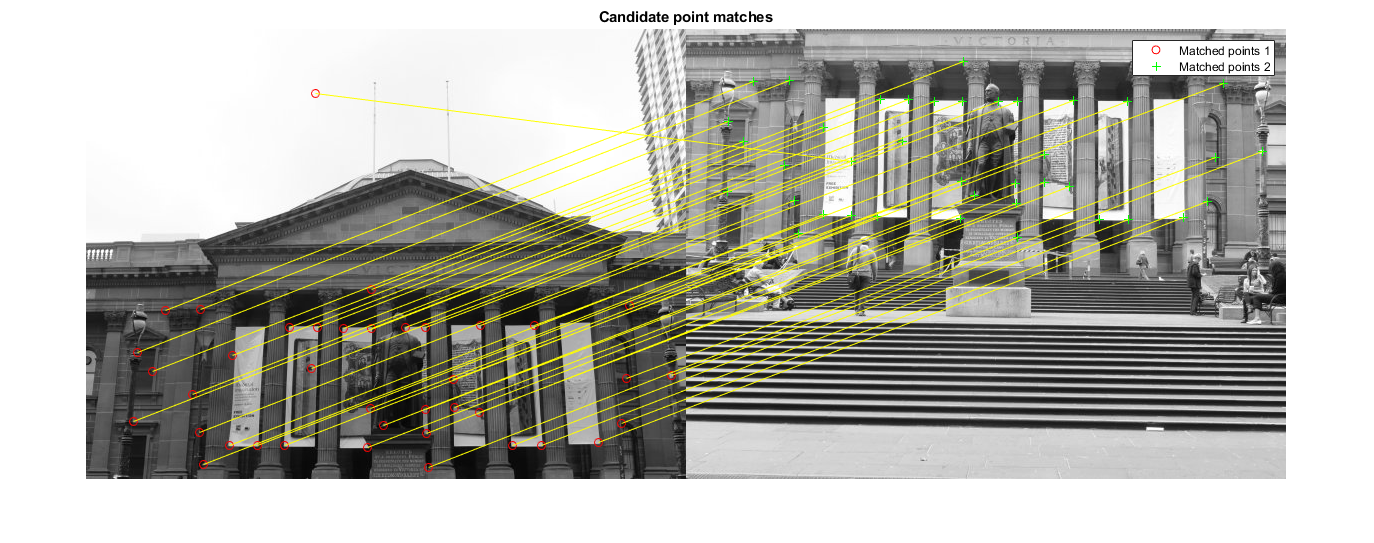

title(ax, 'Candidate point matches');
legend(ax, 'Matched points 1','Matched points 2');


## Show 2

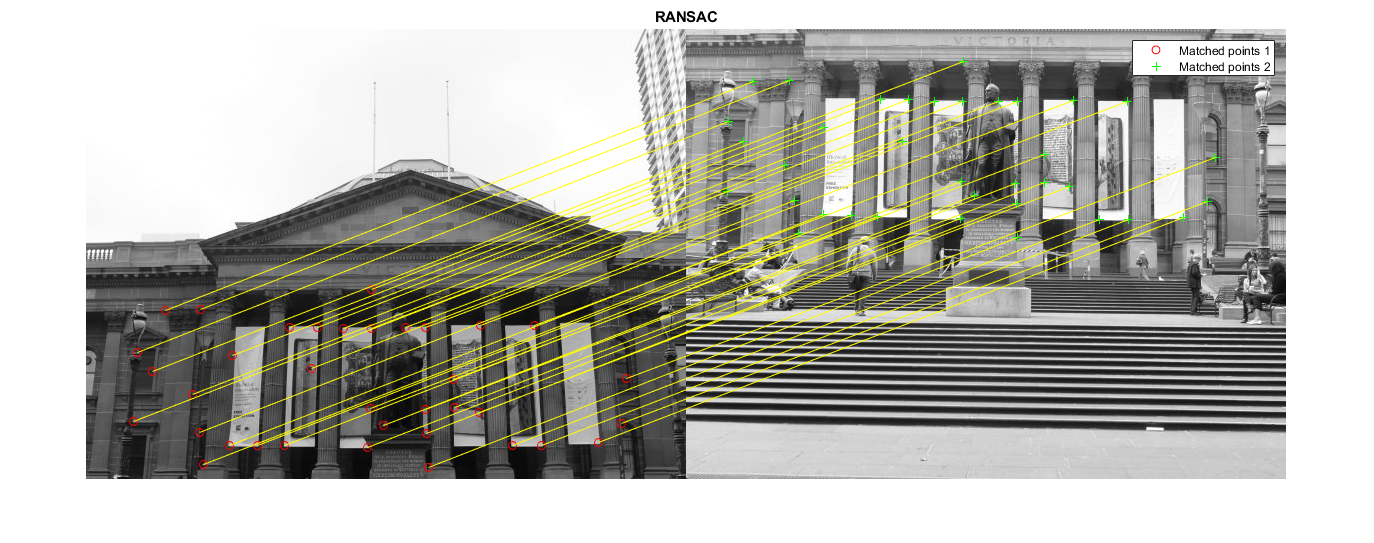

figure; ax = axes;
showMatchedFeatures(train1_1,train1_2,inliers_1,inliers_2,'montage','Parent',ax);
title(ax, 'RANSAC');
legend(ax, 'Matched points 1','Matched points 2');

## Function

function c_best = ANMS(cm,Nbest)

lm = imregionalmax(cm);


[x,y] = find(lm);

N_Strong = size(x,1);

r = inf(1,N_Strong);
ED = 0;

for i = 1:N_Strong
    for j = 1:N_Strong
        if cm(x(j),y(j)) > cm(x(i),y(i))
           ED =  (x(j)-x(i))^2 + (y(j)-y(i))^2;
           if ED < r(i)
              r(i) = ED;
           end 
        end
    end
end    

[sort_r,index] = sort(r,'descend');
c_best = zeros(2,Nbest);

for i = 1:Nbest
    c_best(1,i) = x(index(i)); 
    c_best(2,i) = y(index(i));
end
end

function f_vector = f_descriptor(cbest,I,H)
f_vector = zeros(64,size(cbest,2));
for i = 1:size(cbest,2)
    minx = max(1,cbest(1,i)-20);
    maxx = min(size(I,1),cbest(1,i)+19);
    miny = max(1,cbest(2,i)-20);
    maxy = min(size(I,2),cbest(2,i)+19);
    im_40 = I(minx:maxx,miny:maxy);
    b_40 = imfilter(im_40,H,'replicate');
    b_8 = imresize(b_40,[8 8]);
    f_vector(:,i) = b_8(:);
    f_vector(:,i) = f_vector(:,i) - ones(64,1)*mean(f_vector(:,i));
    f_vector(:,i) = f_vector(:,i)/std(f_vector(:,i));
end
end





